# `mouselab` examples

## Simple visualisations of the anatomy (`average_template`)

Use the function `plotAllenSlice()` to plot a single plane of data from the Allen datasets in CCF space. They provide `average_template (default)`, `ara_nissl`, and `annotation` data. By default, a coronal view is plotted at 100um resolution, 25% of the way along the volume. 

### Default

The first argument should be the type of data to be plotted (`"average_template" (default)`, `"ara_nissl"`, or `"annotation").`

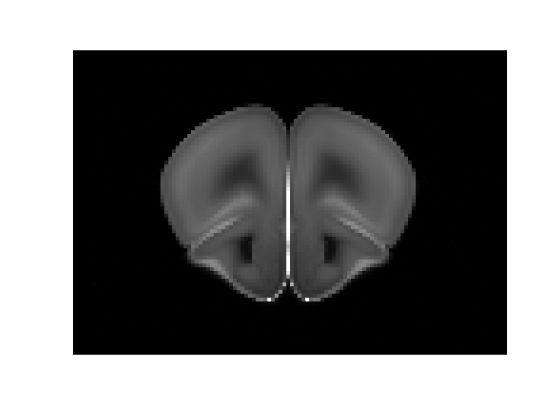

% Ignoring any inputs is the same as `plotAllenSlice("average_template")` 
figure; plotAllenSlice();

### Change resolution

The default resolution is 100um. The repo also includes the data at 50um. The 10um and 25um can also be downloaded (from [https://download.alleninstitute.org/informatics-archive/current-release/mouse_ccf/annotation/ccf_2017/)](https://download.alleninstitute.org/informatics-archive/current-release/mouse_ccf/annotation/ccf_2017/)) and added to the `annotation` directory. 

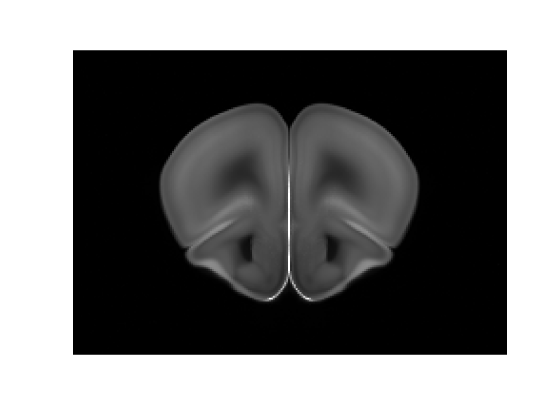

% If specifying other parameters, the first argument must then be specified
figure; plotAllenSlice('average_template', 'resolution', 50); 

### Change slice position

The slice position can be changed using `plotAllenSlice(___, 'slice', value)` syntax in 1 of 2 ways: 

- If `value` is less than 1, the slice `value`% along that axis will be displayed. For example, if `value=0.5`, the middle slice will be displayed; if `value=0.25` (the default), the slice one-quarter of the way along that axis will be displayed. 

- If `value` is greater than or equal to 1, the `value`-th slice will be displated. For example, if `value=100`, the 100th slice will be displayed. 

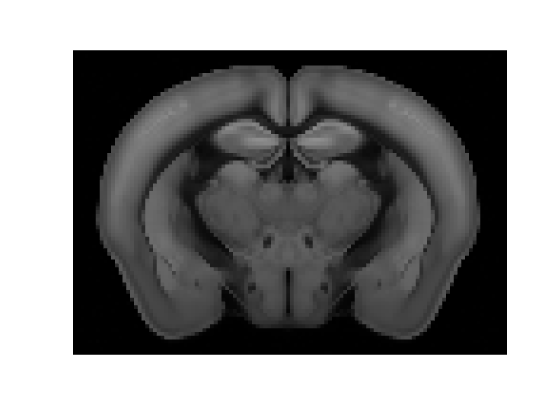

figure; plotAllenSlice('average_template', 'slice', 0.5); 

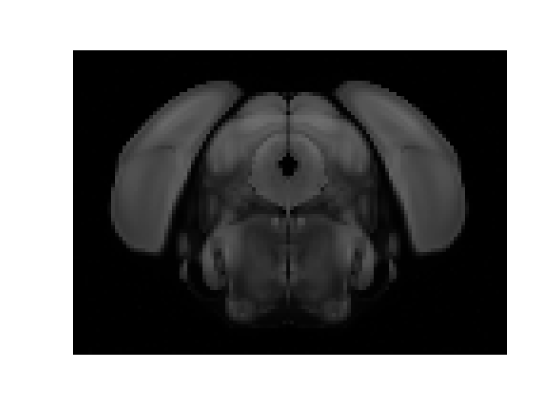

figure; plotAllenSlice('average_template', 'slice', 100); 

### Change slice orientation

The axis along which to slice can be changed using `plotAllenSlice(___, 'dim', value)` syntax. Set `value` to `'s'` for sagital sections, `'t'` for transverse sections, and `'c'` for coronol sections (the default). 

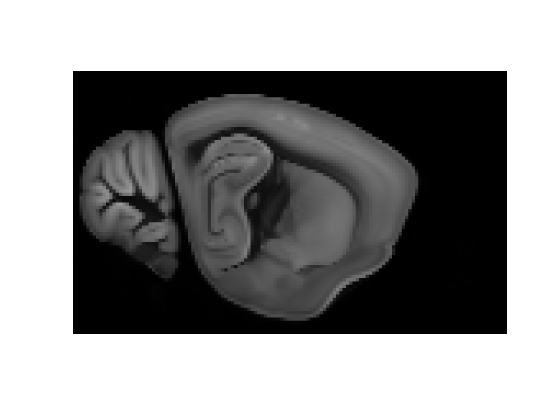

figure; plotAllenSlice('average_template', 'dim', 's'); 

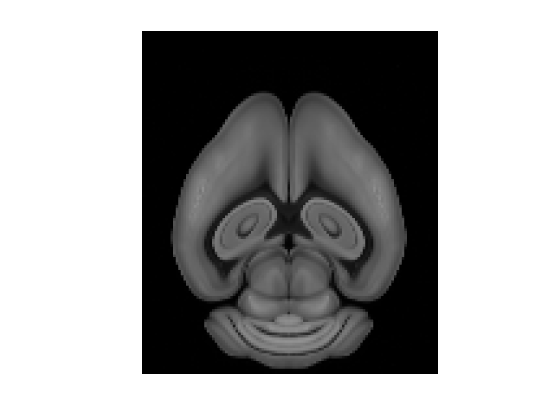

figure; plotAllenSlice('average_template', 'dim', 't'); 

### Change data

If desired, the data to plotted can be changed to the `ara_nissl` or `annotation` data from the Allen Institute. 

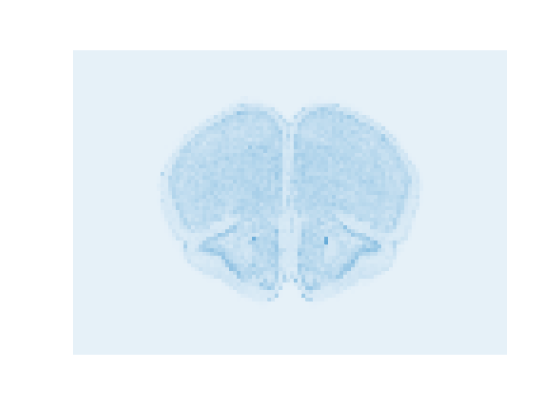

figure; plotAllenSlice('ara_nissl', 'cmap', 'sky'); 

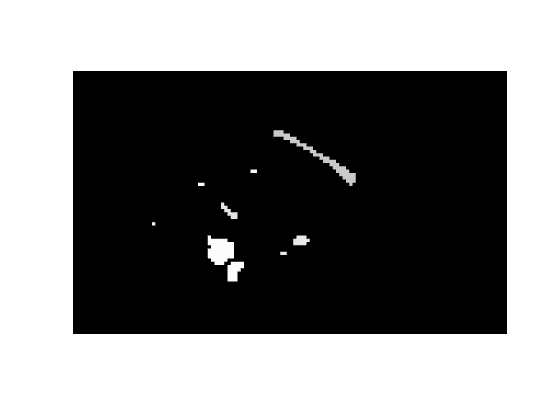

figure; plotAllenSlice('annotation', 'slice', 0.5, 'dim', 's');

### Caveat

The colors in the figure are 'true' colors i.e. the color is set at runtime (see [here](https://au.mathworks.com/help/matlab/ref/matlab.graphics.primitive.patch-properties.html#buduav0-1-FaceVertexCData)/[here](https://au.mathworks.com/help/matlab/creating_plots/differences-between-colormaps-and-truecolor.html)/[here](https://au.mathworks.com/help/matlab/creating_plots/how-patch-data-relates-to-a-colormap.html) for more details). The color values cannot be changed after the figure is generated. However, they can be set using the `cmap` and `clims` name-value arguments. Note that these do not change the colormap/limits of the axes - they only change the way the data is generated for plotting. 

figure; plotAllenSlice('average_template'); colormap(hot); % This will not have an effect

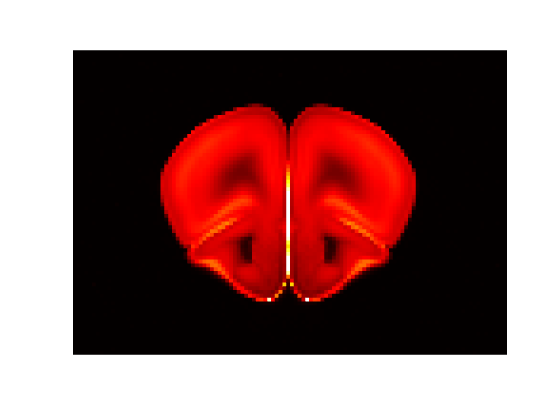

figure; plotAllenSlice('average_template', 'cmap', hot); 

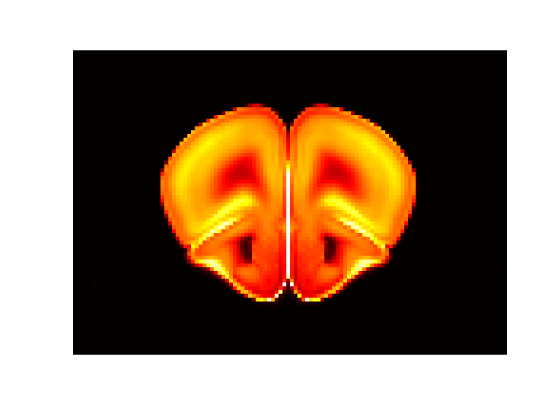

figure; plotAllenSlice('average_template', 'cmap', hot, 'clims', [1 300]); 

## Visualising new data in CCF space

Here, we will use the `ara_nissl` data as example volumetric data in CCF space. But you can use your own data instead.

V = double(getAllenTemplate('ara_nissl')).*logical(getAllenTemplate('annotation'));

### Default

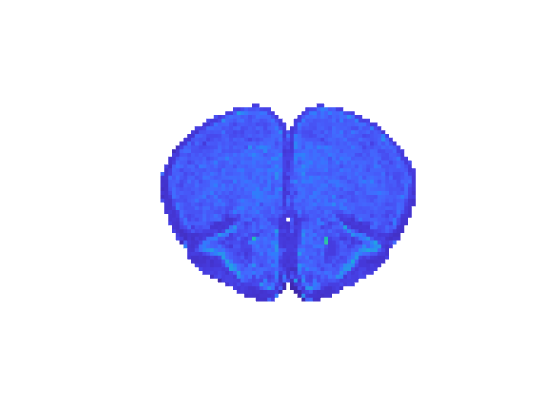

figure; plotCcfAnnotation(V); 

### Changing resolution

The `plotCcfAnnotation` function assumes your data is at 100um resolution and uses this to plot the data in 3D space. Let it know if you are plotting data at a different resolution. 

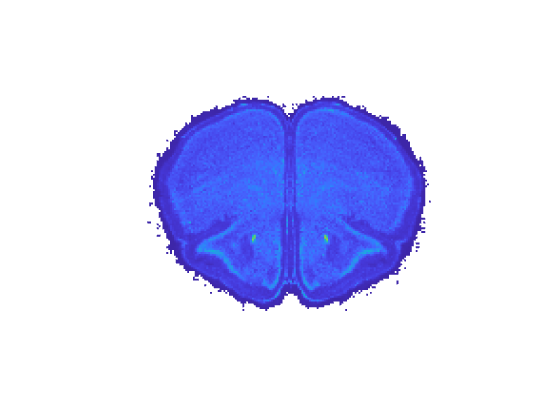

figure; plotCcfAnnotation(getAllenTemplate('ara_nissl', 50), 'resolution', 50); 

### Changing the slice to be visualised

This can be changed the same as for the anatomy. 

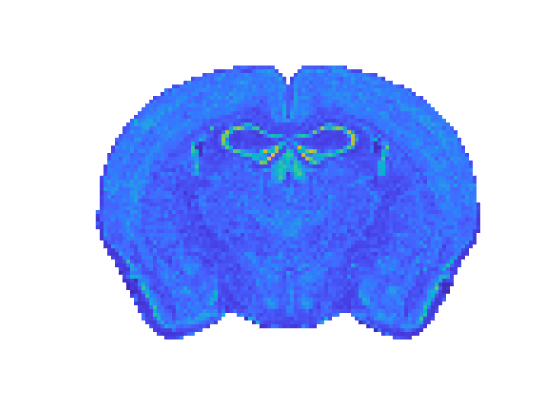

figure; plotCcfAnnotation(V, 'slice', 0.5); 

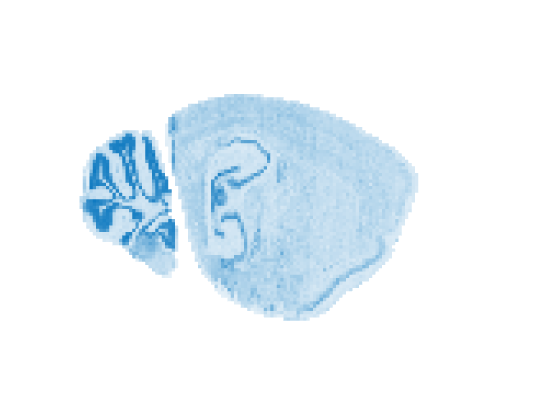

figure; plotCcfAnnotation(V, 'dim', 's'); colormap(sky); 

## Visualising multiple views

Combined views in coronal, sagittal, and transverse planes can be generated using the functions `layoutAllenSlices` and `layoutCcfAnnotations`. 

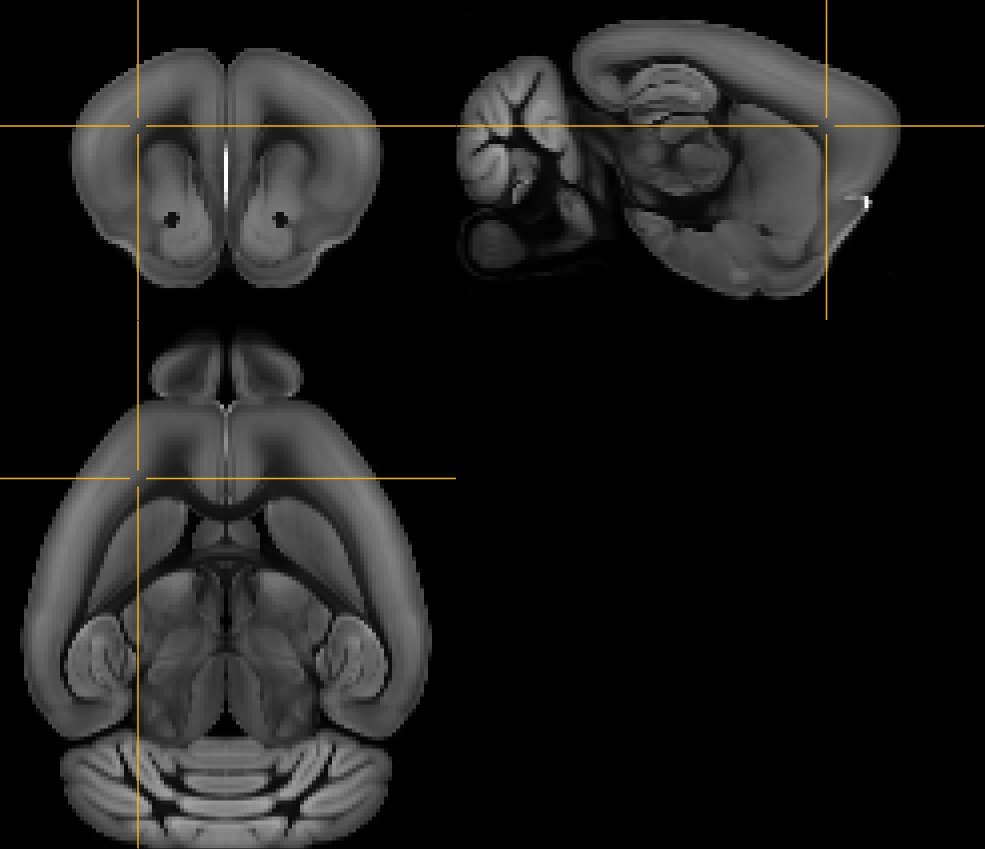

layoutAllenSlices(); 

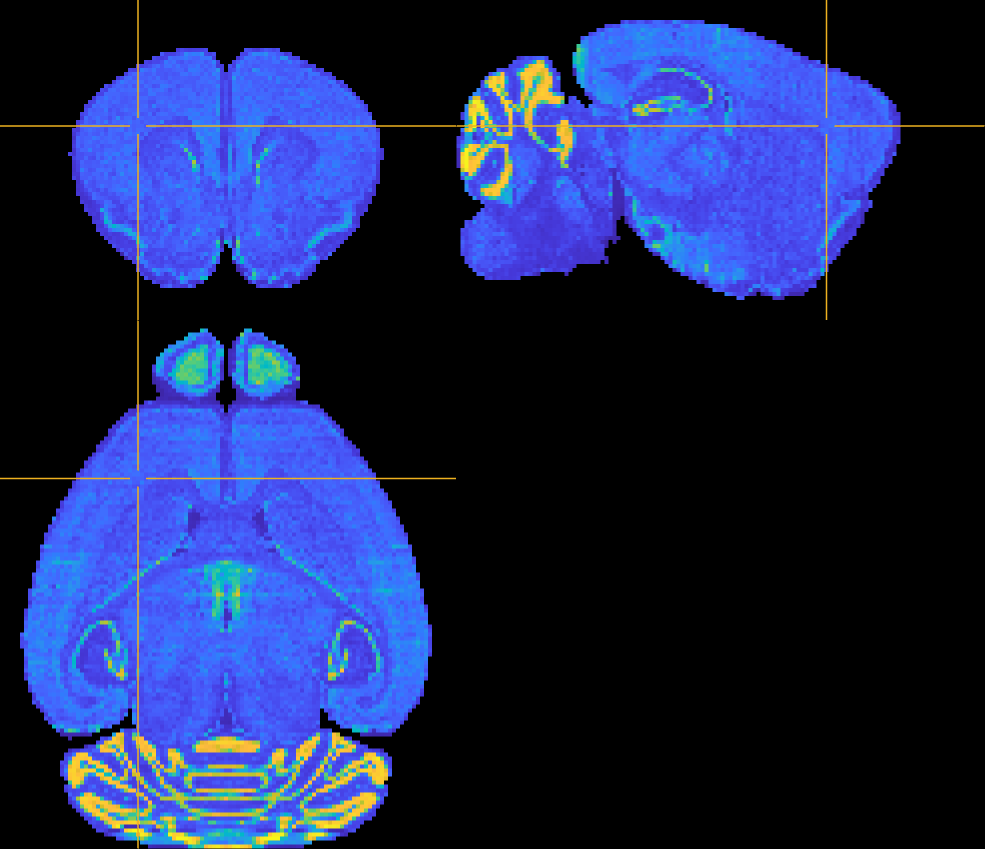

V = double(getAllenTemplate('ara_nissl')).*logical(getAllenTemplate('annotation'));
layoutCcfAnnotations(V); 

The crosshairs indicate where the slices in the other views have been made. 

### Changing the slice location

Use the `'s'`, `'c'`, and `'t'` name-value arguments to change the position of each slice individually, using the syntax as described above. 

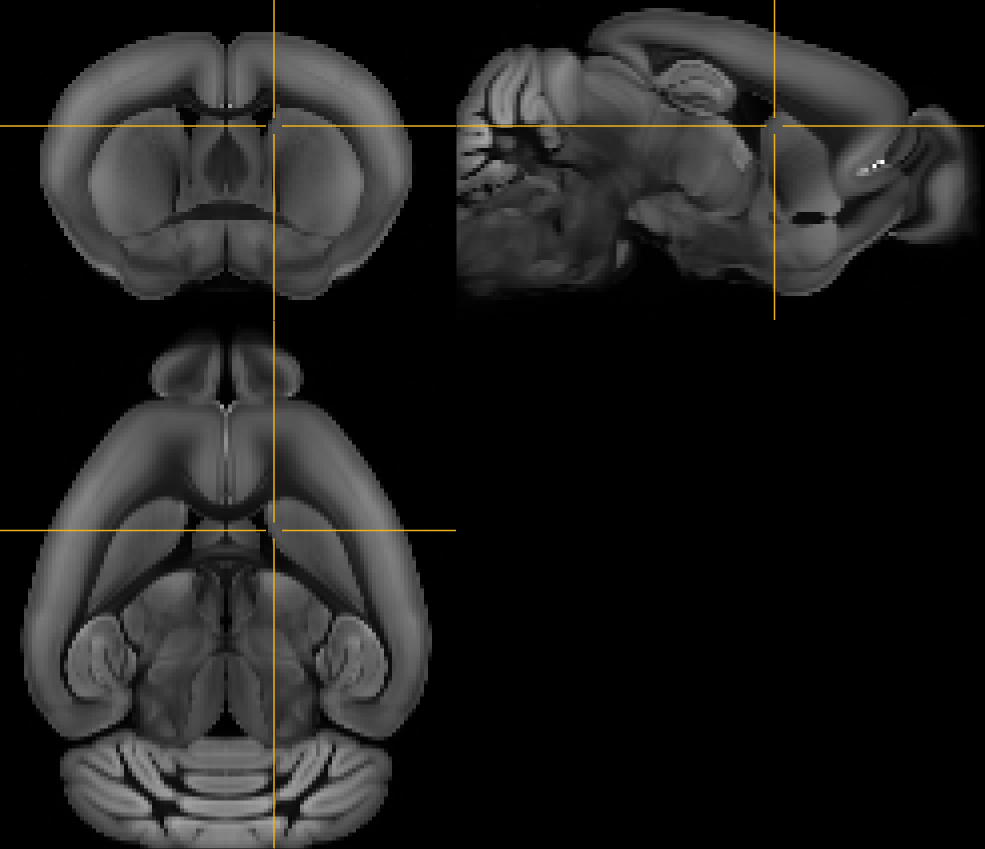

layoutAllenSlices('average_template', 's', .4, 'c', .4, 't', .4); 

### Adding supplementary views

Slices, surface, or volume data can be added in the remaining quadrant of the above image.

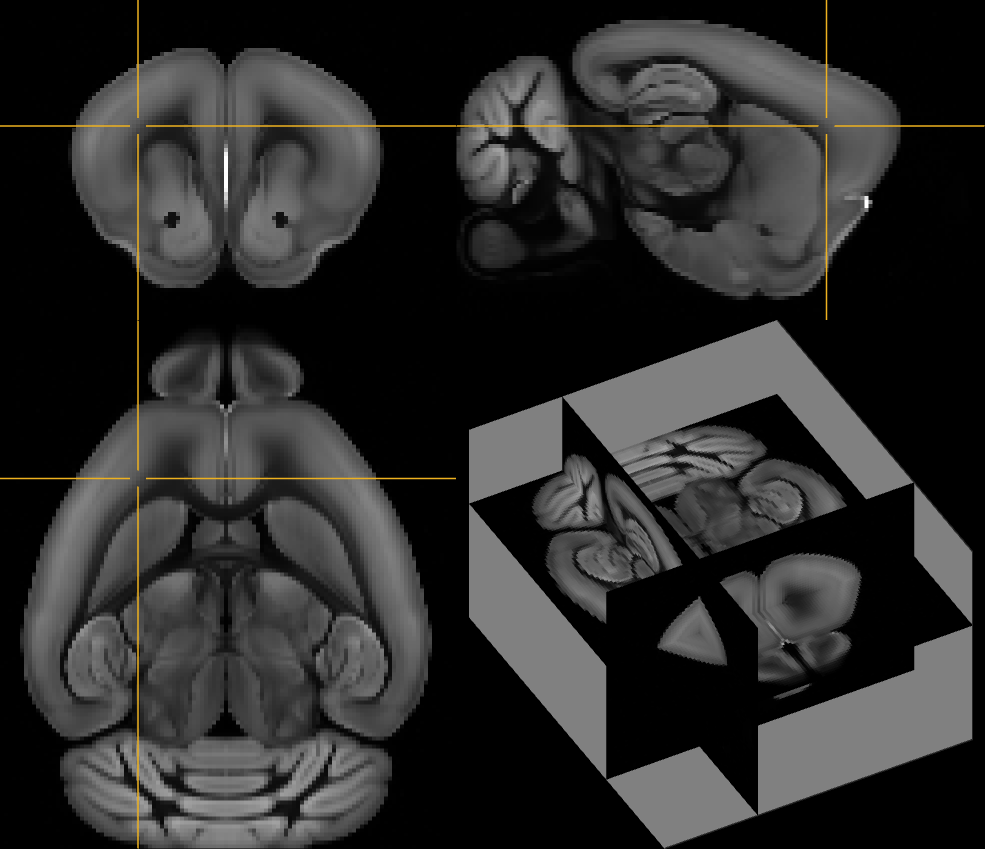

layoutAllenSlices('average_template', 'add', 'slices'); 

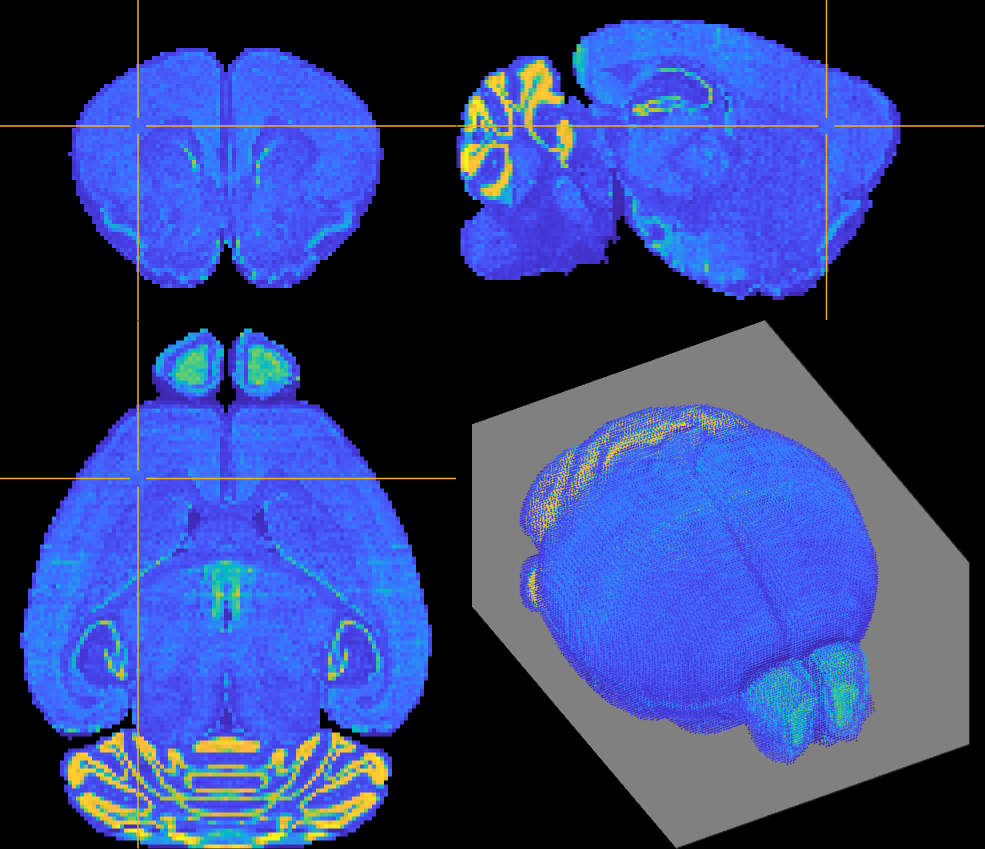

layoutCcfAnnotations(V, 'add', 'volume', 'vertices', V2v(V, getAllenTform(100), 1)); 

## Combining anatomical and volumetric data

Volumetric and anatomical data can be plotted concurrently on a set of axes:

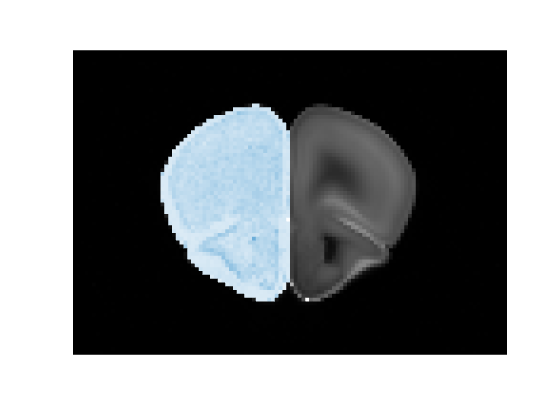

V = maskR(double(getAllenTemplate('ara_nissl')).*logical(getAllenTemplate('annotation'))); % example volumetric data
figure;  plotAllenSlice();
hold on; plotCcfAnnotation(V);
colormap('sky'); % beacuse the volumetric data is scaled color and the anatomical data is true color, the colormap can be change. 

### Combining data at different resolutions

Sometimes data at a higher resolution can mask data at a lower reoslution. Use the "(___`'roundResolution', Y)`" name-value argument to plot data at a resolution X such that it is compatible with data at a resolution Y. 

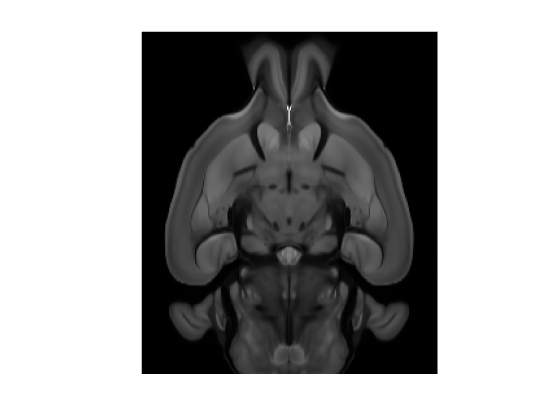

% This will not look good as the figures do not exactly line up
figure;  plotAllenSlice('average_template', 'resolution', 50, 'slice', 0.7, 'dim', 't');
hold on; plotCcfAnnotation(V, 'slice', 0.7, 'dim', 't');

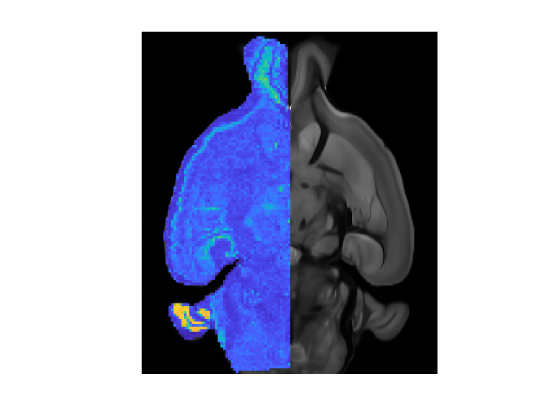

% Using `roundresolution` fixes it
figure;  plotAllenSlice('average_template', 'resolution', 50, 'slice', 0.7, 'dim', 't', 'roundResolution', 2);
hold on; plotCcfAnnotation(V, 'slice', 0.7, 'dim', 't');

### Combining layouts

Use the output from `layoutAllenSlices` with the `'Parent' name-value argument in layoutCcfAnnotations to plot multi-view data concurrently: `

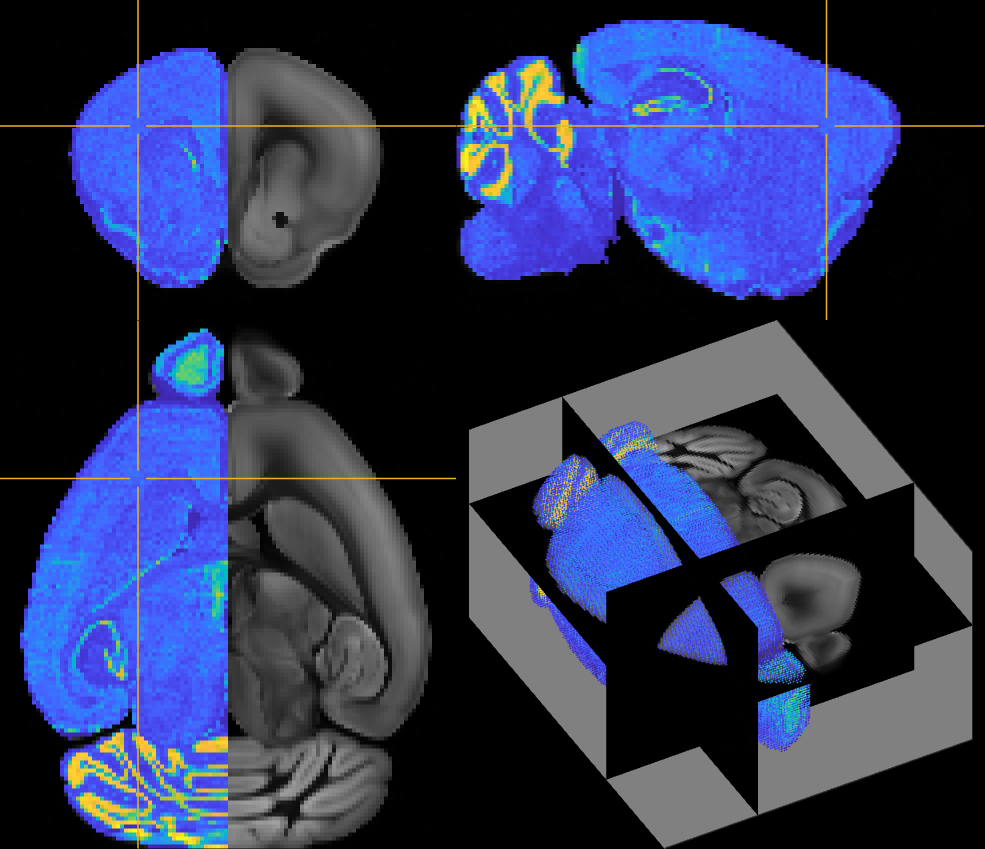

fig = layoutAllenSlices('add', 'slices'); 
layoutCcfAnnotations(V, 'Parent', fig, 'add', 'volume'); 

## A discussion on creating mixed plots with different masks

The Allen data includes 'annotation' and 'average_template' data. The 'average_template' data is similar to T1 and can be used for plotting MR-style images. However, it includes a lot of background noise. The 'annotation' data contains a parcellation of the whole brain, and can further be binarised to be used as a mask.

`plotAllenSlice` can plot this data. By default, it uses a gray colormap and plots the whole volume (zeros, nonzeros etc) i.e. no mask is applied. 

% These are all the same (the supplied arguments are the defaults)
figure; plotAllenSlice();

figure; plotAllenSlice('average_template');

figure; plotAllenSlice('average_template', 'mask', @(x) true(size(x)));

Note that some but not all of the background voxels are zero, and so applying a logical mask looks bad.

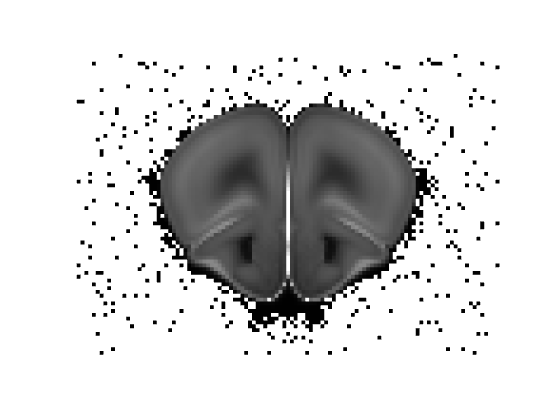

figure; plotAllenSlice('average_template', 'mask', @logical); 

In contrast, using the 'annotation' as a mask results in only the brain voxels being plotted.

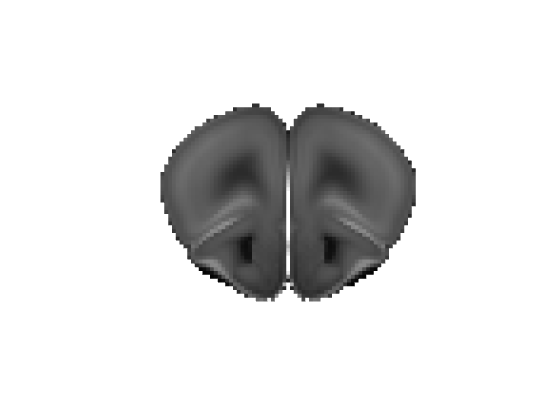

figure; plotAllenSlice('average_template', 'mask', getAllenTemplate('annotation')); 

The colormap of `plotAllenSlice` cannot be changed after figure generation, as a true colour image is being plotted. However, it can be changed at runtime: 

figure; plotAllenSlice('average_template'); colormap('hot'); % this won't work

figure; plotAllenSlice('average_template', 'cmap', 'hot'); % this will

Similar results can be achieved using `plotCcfAnnotation`. This is because `plotAllenSlice` is a wrapper for `plotCcfAnnotation` that simply converts the Allen data to true colour volumes before plotting.

However, some of the defaults are different. Notably, the default mask is the non-zero entries in the matrix. This improves the plotting of the annotation data: 

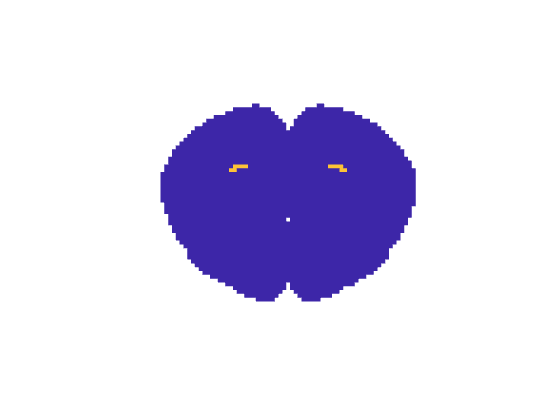

figure; plotCcfAnnotation(getAllenTemplate('annotation'));

It worsens the plotting of the average_template data: 

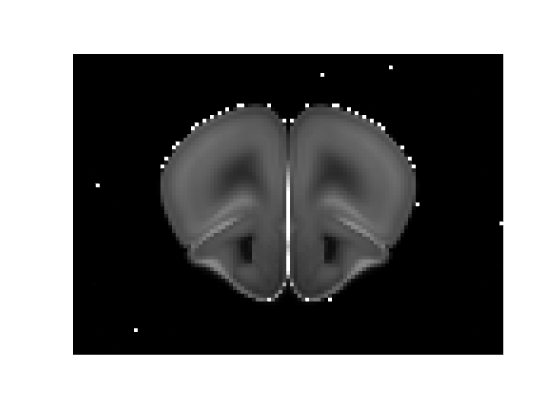

figure; plotCcfAnnotation(getAllenTemplate('average_template')); colormap(gray); 

But this can be readily fixed by using the annotation data as a mask for the average_template: 

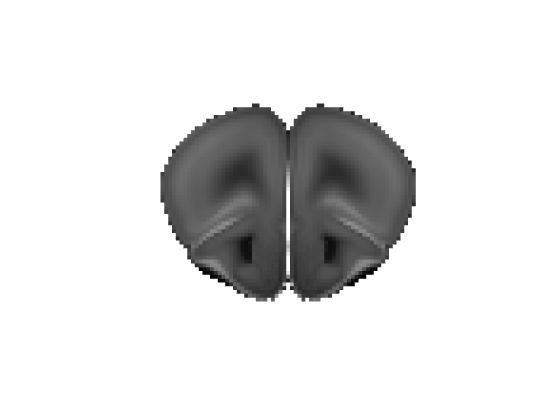

figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', getAllenTemplate()); colormap(gray); 

figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', getAllenTemplate('annotation')); colormap(gray); 

or by plotting the whole volume: 

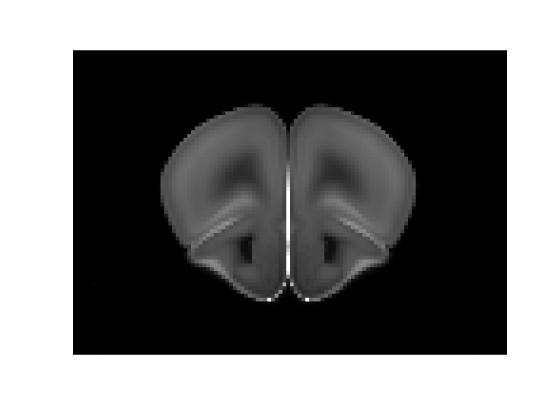

figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', @(x) true(size(x))); colormap(gray); 

figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', ones(size(getAllenTemplate()))); colormap(gray); 

Plotting both background and foreground data can be done by using the two functions together. `plotAllenSlice` is recommended for the background, as it is in true colour. `plotCcfAnnotation` is recommended for the foreground, as it is scaled colour (and so can be modified post-runtime with `colormap`, `clims` etc). 

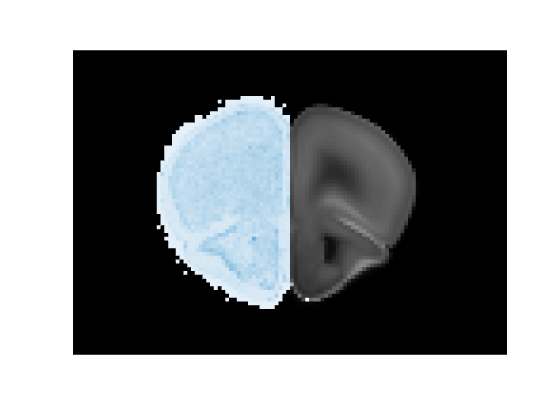

V = getAllenTemplate('ara_nissl', 100, 2); 
figure; 
plotAllenSlice(); 
hold on; 
plotCcfAnnotation(V); 
colormap(sky); 

% % A large list of foreground and background plots/options
% figure; plotCcfAnnotation(getAllenTemplate('annotation'));
% figure; plotCcfAnnotation(getAllenTemplate('annotation'), 'mask', getAllenTemplate('annotation'));
% figure; plotCcfAnnotation(getAllenTemplate('annotation'), 'mask', @logical);
% figure; plotCcfAnnotation(getAllenTemplate('annotation'), 'mask', @(x) true(size(x)));
% 
% figure; plotCcfAnnotation(getAllenTemplate('average_template')); colormap(gray); 
% figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', getAllenTemplate('annotation')); colormap(gray); 
% figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', @logical); colormap(gray); 
% figure; plotCcfAnnotation(getAllenTemplate('average_template'), 'mask', @(x) true(size(x))); colormap(gray); 
% 
% figure; plotAllenSlice('annotation', 'cmap', parula);
% figure; plotAllenSlice('annotation', 'cmap', parula, 'mask', getAllenTemplate('annotation'));
% figure; plotAllenSlice('annotation', 'cmap', parula, 'mask', @logical);
% figure; plotAllenSlice('annotation', 'cmap', parula, 'mask', @(x) true(size(x)));
% 
% figure; plotAllenSlice('average_template');
% figure; plotAllenSlice('average_template', 'mask', getAllenTemplate('annotation')); % bad
% figure; plotAllenSlice('average_template', 'mask', @logical); 
% figure; plotAllenSlice('average_template', 'mask', @(x) true(size(x)));

## Creating animations using `videofig(s) `from `nihelp`

`These animations cannot be created in a live script, but have a look at the examples below and in the test files. `

% videofig(132, @(n) plotAllenSlice('average_template', 'slice', n));


%% Compare high res nissl with low res MRI
% V = getAllenTemplate('ara_nissl',50).*getAllenRMask(50); % example volumetric data
% videofigs(132, @(n) cla, @(n) plotAllenSlice('dim', 'c', 'slice', n, 'resolution', 100), ...
%     @(n) hold('on'), @(n) plotCcfAnnotation(V, 'dim', 'c', 'slice', n*2-1, 'resolution', 50), ...
%     @(n) colormap('sky'));